# Compute Watershed Transform and Display Resulting Label Matrix

Create a binary image containing two overlapping circular objects. Display the image.

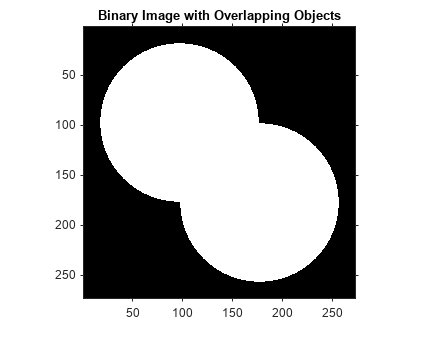

center1 = -40;
center2 = -center1;
dist = sqrt(2*(2*center1)^2);
radius = dist/2 * 1.4;
lims = [floor(center1-1.2*radius) ceil(center2+1.2*radius)];
[x,y] = meshgrid(lims(1):lims(2));
bw1 = sqrt((x-center1).^2 + (y-center1).^2) <= radius;
bw2 = sqrt((x-center2).^2 + (y-center2).^2) <= radius;
bw = bw1 | bw2;
imshow(bw)
title('Binary Image with Overlapping Objects')

Calculate the distance transform of the complement of the binary image. The value of each pixel in the output image is the distance between that pixel and the nearest nonzero pixel of `bw`.

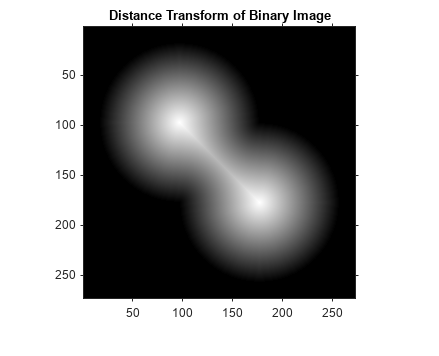

D = bwdist(~bw);
imshow(D,[])
title('Distance Transform of Binary Image')

Take the complement of the distance transformed image so that light pixels represent high elevations and dark pixels represent low elevations for the watershed transform.

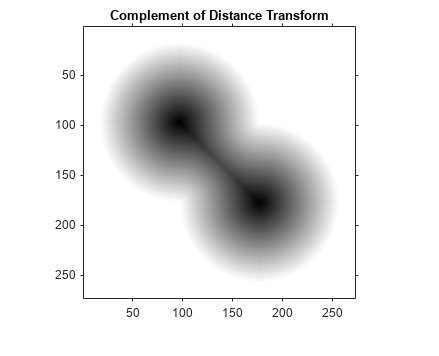

D = -D;
imshow(D,[])
title('Complement of Distance Transform')

Calculate the watershed transform. Set pixels that are outside the ROI to `0`.

L = watershed(D);
L(~bw) = 0;

Display the resulting label matrix as an RGB image.

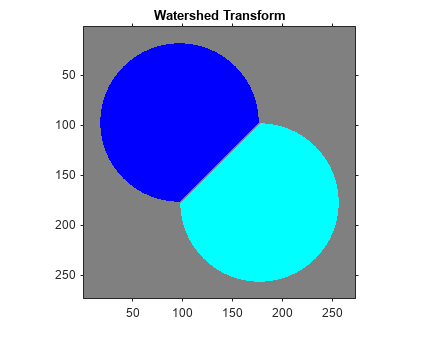

rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb)
title('Watershed Transform')

*Copyright 2015 The MathWorks, Inc.*